clear;
N = 10; %amount off samples averaged
ts = 1/500; %sampling frequency 
z = tf('z',ts) %creating descrite transfer function variable

z =
 
  z
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties



C = 1/N * tf([1],[1 1 1 1 1 1 1 1 1 0])

C =
 
                         0.1
  -------------------------------------------------
  s^9 + s^8 + s^7 + s^6 + s^5 + s^4 + s^3 + s^2 + s
 
Continuous-time transfer function.
Model Properties


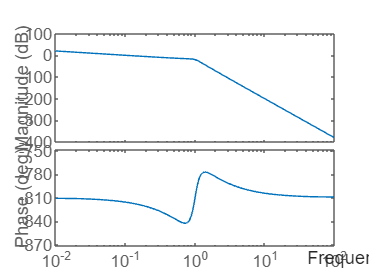

bode(C)

pole(C)

ans =    0.0000 + 0.0000i
   0.7660 + 0.6428i
   0.7660 - 0.6428i
   0.1736 + 0.9848i
   0.1736 - 0.9848i
  -0.9397 + 0.3420i
  -0.9397 - 0.3420i
  -0.5000 + 0.8660i
  -0.5000 - 0.8660i
